# Heat Conduction Through Iron Rod

This example shows how thermal blocks can model a long iron rod that is fixed to a hot base at one end and exposed to air along its length and at its free end. The rod is an extended surface that undergoes conduction along its length and convection with air in the direction perpendicular to its length. Extended surfaces are often used as fins to cool a solid.

In this scenario, the base is fixed to a wall with a temperature of 100 degrees Celsius. Heat transfers down the rod through conduction, gradually heating the rod's thermal mass. Heat escapes the rod cylindrical surface and free end through natural convection with ambient air that has a temperature of 20 degrees Celsius. The entire rod temperature initially equals the ambient air temperature. The temperature along the rod reaches steady state after approximately 1500 seconds. The rod is made of iron, is 20 cm in length and 2.5 cm in diameter.

This example initially describes the fundamental thermal effects in the rod: the governing law of energy conservation, the heat transfer mechanisms of conduction and convection, and the property of thermal mass. Then, this example combines the thermal effects to consider two complete thermal models of the rod. The first thermal model contains a single lumped mass while the second is a finite difference model with multiple lumped masses. This example considers the computational cost and fidelity trade-offs of the two different thermal models for the rod. This example compares how well the models converge with the analytical steady-state solution.

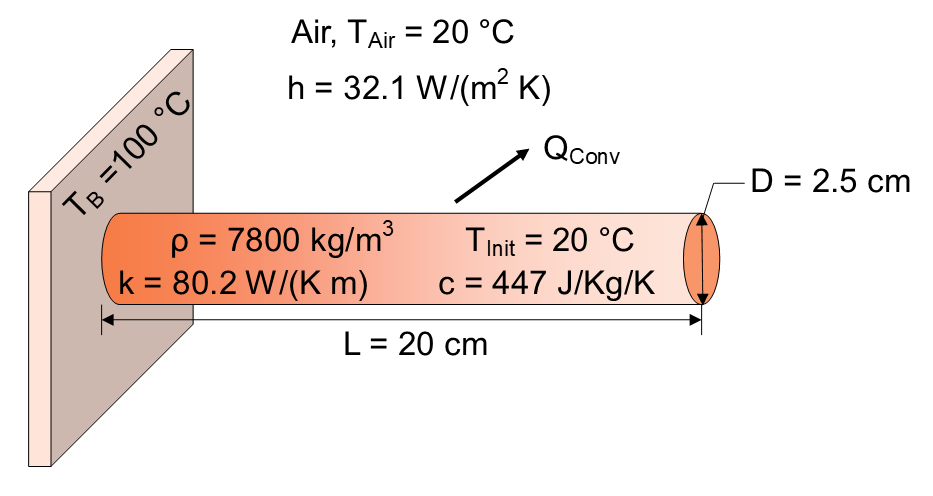

% Model parameters

% Thermal conditions
T_air     = 20;        % Air temperature           [degC]
T_base    = 100;       % Base temperature          [degC]
T_init    = T_air;     % Initial rod temperature   [degC]

% Geometric parameters
L         = 0.2;       % Rod length                [m]
D         = 0.025;     % Rod diameter              [m]
A         = pi*D^2/4;  % Rod cross-sectional area  [m^2]
A_cyl     = pi* D * L; % Rod cylindrical surface area [m^2]

% Iron material properties
rho       = 7800;      % Iron density              [Kg/m^3]
k         = 80.2;      % Iron thermal conductivity [W/(K*m)]
h         = 32.1;      % Convective heat transfer coefficient [W/(m^2*K)]
c         = 447;       % Iron specific heat [J/kg/K]

m         = rho*A*L;   % Rod mass [kg]

## Law of Energy Conservation

The first law of thermodynamics is a fundamental principle in physics stating that the total energy of an isolated system remains constant over time. This law is expressed mathematically in terms of power as,

$\frac{dU}{dt} = Q - W$.

Where:

- $\frac{\textrm{dU}}{\textrm{dt}}$ is the rate of change in internal energy with respect to time (measured in *W* in SI units).

- $Q$ is the rate of heat added to the system (measured in *W*).

- $W$ is the rate of work done by the system (measured in *W*).

In thermal systems where no work occurs, the rate of change in internal energy equals the rate of heat added to the system,

$\frac{dU}{dt} = Q $.

In the iron rod, conduction and convection heat transfer ($Q$) change the internal energy stored in the rod's thermal mass ($U$).

## Conduction

Thermal conduction is the process of heat transfer through a material. When the material is heated, its molecules gain kinetic energy, leading to increased motion. This heightened motion causes collisions with neighboring molecules, transferring energy in the process. This transfer continues until thermal equilibrium is achieved, resulting in a uniform temperature throughout the substance.

The thermal conduction equation, also known as Fourier's law, describes the rate of heat transfer through a material,

$Q =k \frac{A}{L} (T_1 - T_2)$,

where:

- $Q$ is the heat flow from end $1$ to end $2$ (measured in *W*).

- $k$ is the thermal conductivity of the material (measured in *W/(K m)*).

- $A$ is the area normal to the heat flow direction (measured in *m^2*).

- $L$ is the thickness in the heat flow direction (measured in *m*).

- $T_1$ and $T_2$ are the temperatures at either end of the conductive heat transfer element (measured in *degC*).

### Example 1 - Steady State Conduction

Consider a simplified scenario for the rod: The rod is insulated so that there is no convective heat transfer with the air along its length. A constant 18 W of heat flows through the rod and out the rod tip. What is the temperature of the rod tip?

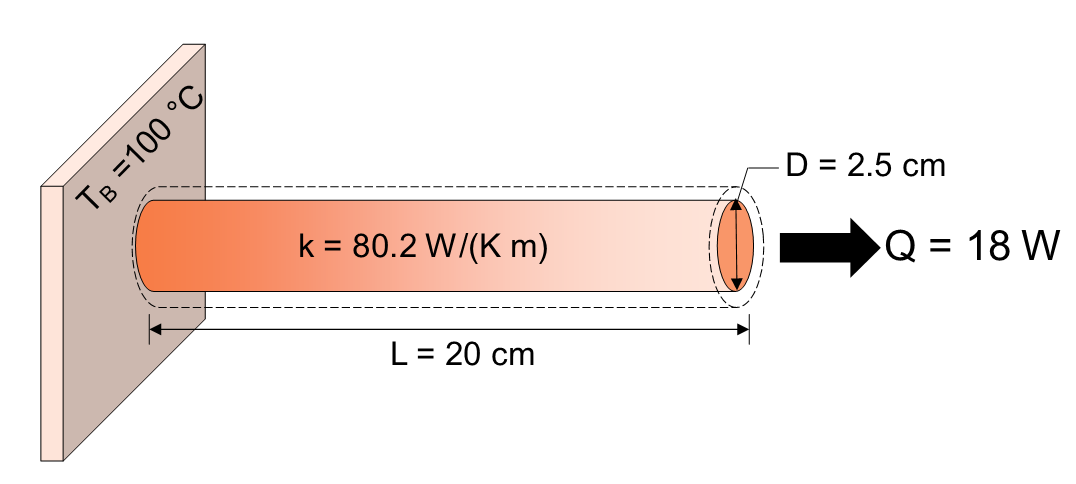

Rearranging the thermal conduction equation, you expect that the temperature at the rod tip is,


$$T_{End} =  T_{Base} - \frac{L}{A  k} Q$$


% Example parameter
Q_case_1  = 18;       % Heat flow rate through rod [W]

% Expected rod tip temperature
T_rod_tip_steady_case_1 = T_base - L/(A*k)*Q_case_1 % [degC]

Open the model HeatConductionThroughInsulatedIronRod to verify the analytical solution. The thermal model consists of a Temperature Source set to the base temperature, a Conductive Heat Transfer element, and a Heat Flow Rate source set to 18 W.

mdl = 'I_HeatConductionThroughInsulatedIronRod';
open_system(mdl);

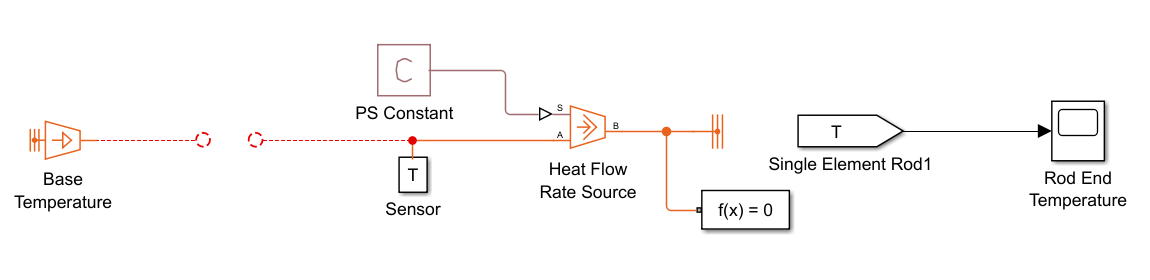

Simulate the model and compare the simulation results to the analytical solution.

sim(mdl);
% Get the simulation output
T = yout; % [degC]

% Display the temperature 
T_rod_tip_simulated_case_1 = T(end) % [degC]

The simulation results agree with the analytical solution.

## Convection

Convection is the process of heat transfer through the movement of a fluid. The movement of fluid combined with conduction leads to the transport of heat energy from hotter regions to cooler regions within the fluid. Natural convection occurs in a fluid due to density differences caused by temperature gradients. When a fluid is heated, it becomes less dense and tends to rise, while cooler, denser fluid moves in to replace it. This sets up a circulation pattern within the fluid, where heat is transported from hotter regions to cooler regions.

The thermal convection equation, known as Newton's law of cooling, describes the rate of heat transfer from a surface to the surrounding fluid,

$Q =h  A _{Conv}(T_1 - T_2)$,

where:

- $h$ is the convective heat transfer coefficient (measured in *W/(K m^2)*).

- $A_{\textrm{Conv}}$ is the surface area (measured in *m^2*).

- $T_1$ and $T_2$ are the temperatures of the surface and surrounding fluid, respectively (measured in *degC*).

### Example 2 - Steady State Convection

Consider another simplified scenario for the rod. The entire rod temperature is maintained at 55 degrees Celsius. The ambient temperature is 20 degrees Celsius, and the convective heat transfer coefficient between the rod and air is 32.1 W/(m^2 K). What is the rate of heat transfer between the rod's cylindrical surface and the air?

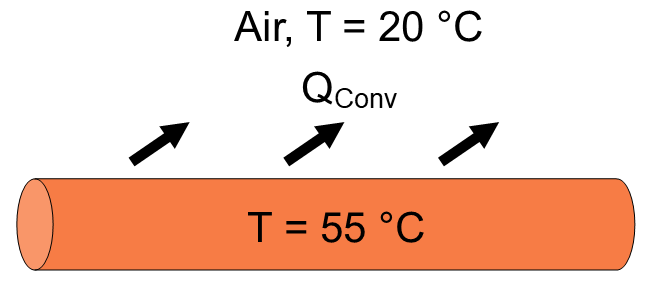

Substitute model parameters into the thermal convection equation to calculate the rate of heat transfer.

% Example parameter
T_cyl_uniform_case_2 = 55;       % Rod uniform temperature [degC]

% Expected rate of convective heat transfer
Q_conv_case_2 = h * A_cyl * (T_cyl_uniform_case_2 - T_air) % [W]

Use the model HeatConvectionFromIronRod to verify the analytical solution. The thermal model consists of a Convective Heat Transfer element in between a Temperature Source set to the rod temperature and a Temperature Source set to the ambient temperature.

mdl = 'II_HeatConvectionFromIronRod';
open_system(mdl);

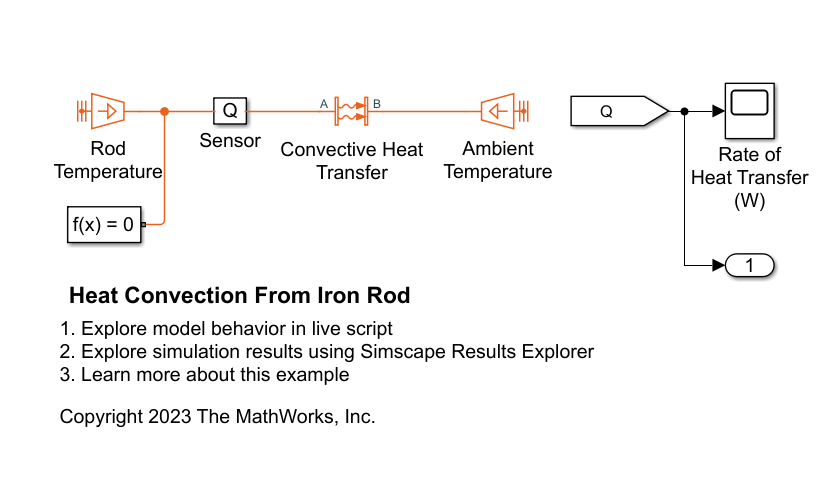

Simulate the model and compare the simulation results to the analytical solution.

sim(mdl);

% Get the simulation output
Q = yout; % [W]

% Display the rate of heat transfer
Q_conv_simulated_case_2 = Q(end) % [W]

The simulated results agree with the analytical solution.

## Thermal Mass

Thermal mass reflects a material's ability to store and release heat energy. The change in internal energy of a thermal mass is represented by the equation,

$\frac{dU}{dt}= c  m \frac{dT}{dt}$,

where:

- $\frac{\textrm{dU}}{\textrm{dt}}$ is the rate of change in internal energy with respect to time (measured in *W*). 

- $c$ is the specific heat of the material (measured in *J/(Kg K)*).

- $m$ is the mass (measured in *kg*).

- $T$ is the temperature (measured in *degC* or *K*).

The rate of change in internal energy of the material, $U$, is proportional to its rate of change in temperature, $T$. The specific heat capacity, $c$, represents the amount of energy required to change the temperature of a unit mass of the material by one degree. Large thermal mass, $\textrm{cm}$,  slows down temperature changes in a system.

### Example 3 - Transient Temperature Response in a Thermal Mass

Consider a simplified scenario of the rod. In this scenario, 18 W of heat flows into a perfectly insulated rod. For simplicity, assume that the entire rod heats up uniformly. At what rate will the rod temperature increase?

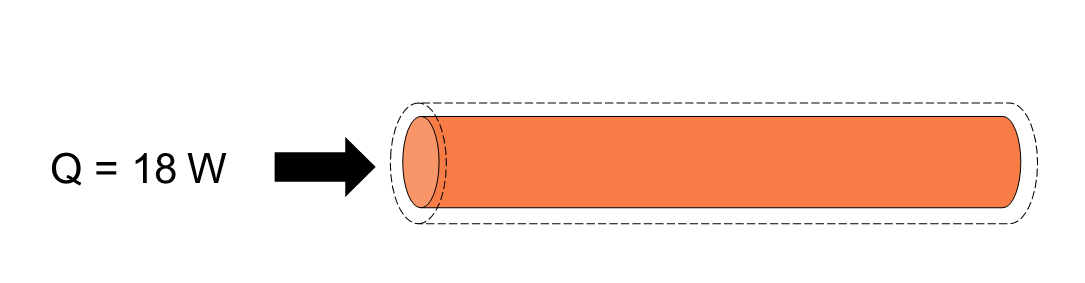

Using the first law of thermodynamics, the heat flowing into the insulated rod equals the change in internal energy of the rod,

$Q = c  m \frac{dT}{dt}$.

Rearrange the equation to solve for the rate of temperature change.

% Example parameter
Q_case_3  = 18;       % Heat flow rate through rod [W]
% Expected rate of temperature change
dT_dt_case_3 = Q_case_3 / (c*m) % Rate of temperature change [degC/sec]

Use the model ThermalMassIronRod to verify the analytical solution.

mdl = 'III_ThermalMassIronRod';
open_system(mdl);

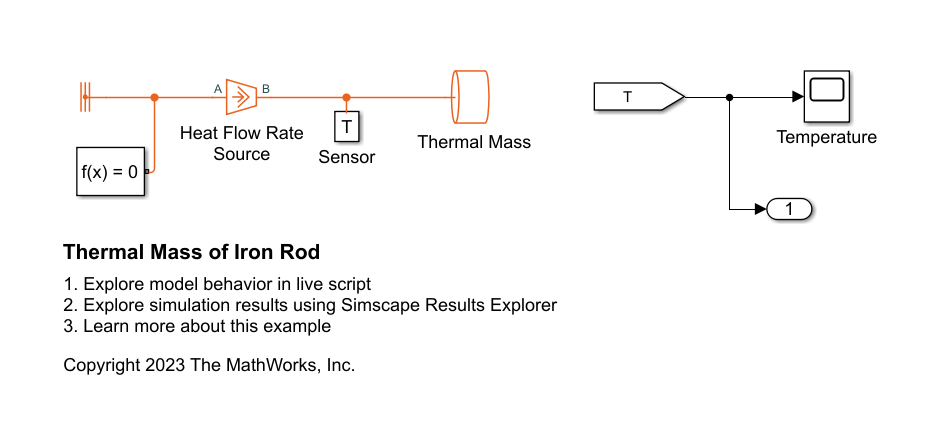

Simulate the model and check that the simulation results match the analytical solution.

sim(mdl);

% Get the simulation output
T = yout; % [degC]
t = tout; % [sec]

% Calculate rate of temperature change
dT = T(end) - T(1);
dt = t(end) - t(1);
dT_dt_simulated_case_3 = dT / dt % [degC/sec]

The simulated results agree with the analytical solution.

## Rod with Transient Thermal Behavior

Combine conductive, convective, and thermal mass elements to fully model the rod with transient behavior. The rod has a base temperature of 100 degrees Celsius. The rod undergoes conduction along its length as well as natural heat convection with air along its length and at its tip. The rod temperature is initially equal to the ambient air temperature of 20 degrees Celsius.

### Lumped Mass Rod Model

A simple model for capturing the transient thermal behavior of the rod contains a single thermal mass. Open the model HeatConductionTroughIronRodLumped.

lumped_mass_model = 'IV_HeatConductionThroughIronRodLumped';
open_system(lumped_mass_model)

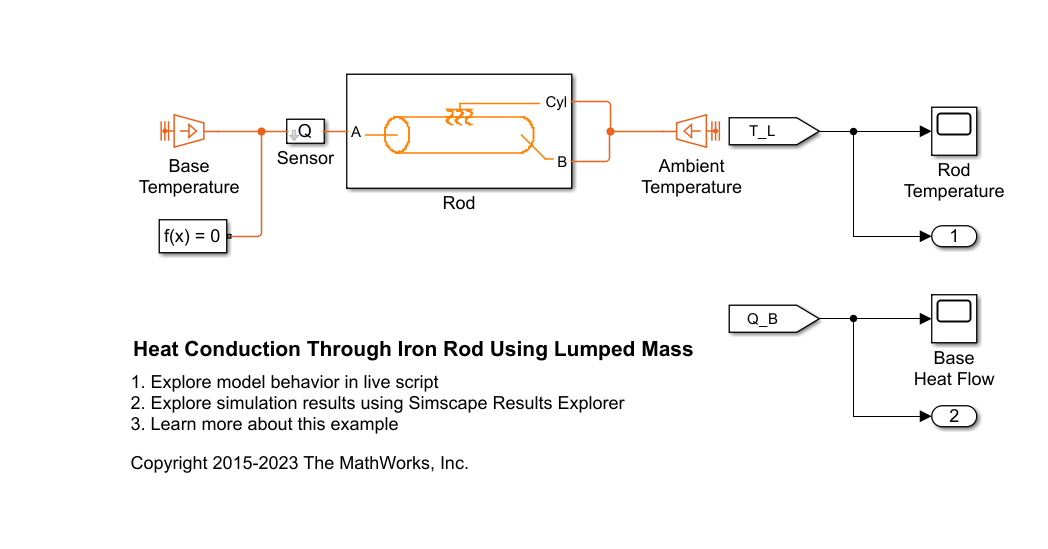

Here is the Rod subsystem.

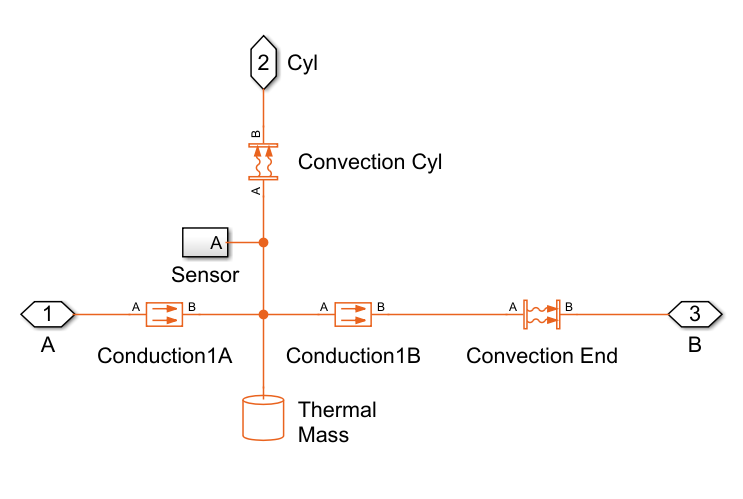

In the Rod model, an intermediate node between two equally divided Conductive Heat Transfer elements represents the rod midpoint. A single thermal mass at the intermediate node models the entire rod mass as maintaining the midpoint temperature. Convective heat transfer elements model convection from the rod cylindrical surface and rod endpoint to the surrounding atmosphere.

Using the first law of thermodynamics, the rate of change in internal energy of the thermal mass equals the net heat flow through the intermediate node:

$\frac{dU}{dt} = Q $.

Net heat flow into the node is due to conduction from the base, convection with the air along the cylindrical surface, and conduction/convection at the rod tip:

$Q = Q_{Left} + Q_{Cyl} + Q_{Right} $.

On the left side of the intermediate node, the heat flows into the node due to conduction from the base:

$Q_{Left} = k \frac{2A}{L}(T_{Base} - T)$,

where $T$ is the temperature of the intermediate node.

Along the cylindrical surface of the rod, heat flows out of the node due to convection with the air:

$Q_{Cyl} = h A_{Cyl}(T_{Air} - T)$.

On the right side of the intermediate node, heat flows out through conduction in the rod and then by convection between the rod tip and air:

$Q_{Right} = k \frac{2A}{L}(T_{End} - T)$,

$Q_{Right} = h A(T_{Air} - T_{End})$,

where $T_{\textrm{End}}$ is the temperature of the rod tip, corresponding to the junction of the *Conduction1B *B port and the *Convection End* A port in the Simscape™ model. Rearrange the $Q_{\textrm{Right}}$ equations to eliminate $T_{\textrm{End}}$:

$Q_{Right} = \frac{2Akh(T_{Air} - T)}{Lh + 2k}$.

Substituting the heat flow expressions and thermal mass internal energy change expression into the energy conservation equation results in the governing differential equation for temperature of the rod, $T$:

$ c m \frac{dT}{dt} = k \frac{2A}{L}(T_{Base} - T) + h A_{Cyl}(T_{Air} - T) + \frac{2Akh( T_{Air} - T)}{Lh + 2k}$.

The Simscape network sums heat transfer at the nodes and is equivalent to this differential equation.

### Segmented Rod Model

A more complex model for capturing the transient thermal behavior of the rod consists of a multiple thermal masses. Open the Segmented Rod model.

segmented_mass_model = 'V_HeatConductionThroughIronRodSegmented';
open_system(segmented_mass_model)

% Model parameters that are not already defined in the live script
num_segments = 9; % [-]

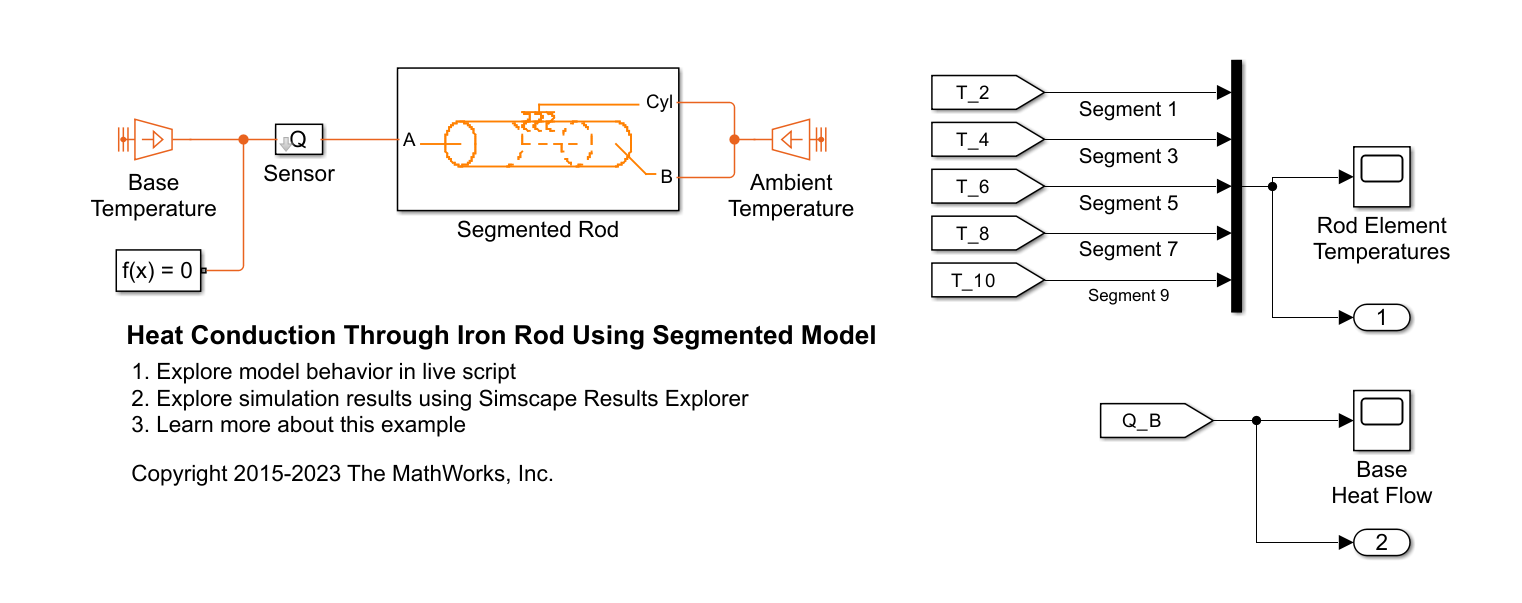

Here is the Segmented Rod subsystem.

open_system([segmented_mass_model '/Segmented Rod'])

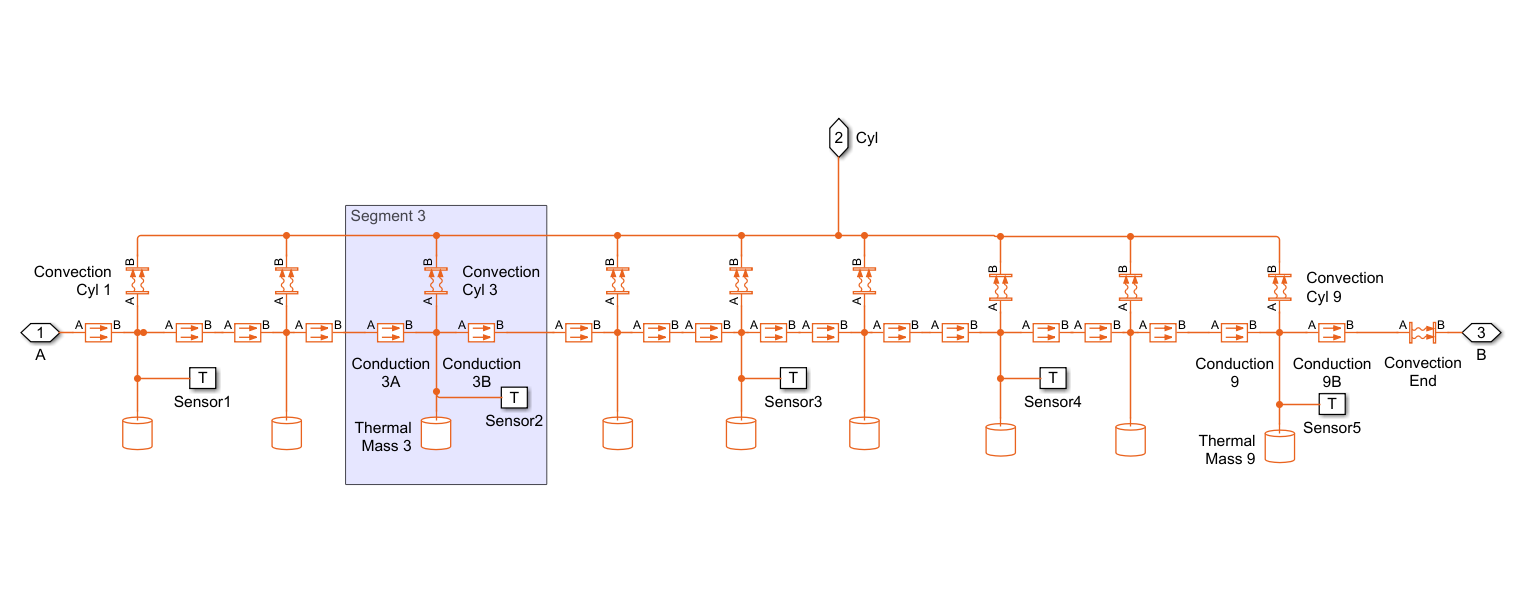

The Segmented Rod model represents the rod as a set of 9 segments connected in series. Each segment has the same structure as the single lumped mass model and contains:

- One thermal mass that is ${1/9}^{\textrm{th}}$ of the overall thermal mass,

- Two conductive heat transfer elements that are each ${1/18}^{\textrm{th}}$ of the rod length, 

- One convective heat transfer element that has ${1/9}^{\textrm{th}}$ the overall cylindrical surface area.

In this example, the choice of 9 segments is not strictly necessary. Choosing an odd number of segments places a node at the mid-point. In general, increasing the number of segments makes the solution converge closer to the analytical solution. After a sufficient number of segments, adding more segments has a negligible effect on convergence. You can modify this example to add more segments. 

Use the first law of thermodynamics to define the governing equation for the nodal temperature in each segment. In each segment, the rate of change in internal energy equals the net heat flow through the segment:

$\frac{dU_i}{dt} = Q_i$.

The rate of change of internal energy stored in the $i^{\textrm{th}}$ segment is:

$\frac{dU_i}{dt} =  c m_{Segment} \frac{dT_i}{dt} $,

where:

- $T_i$ is the temperature of the $i^{\textrm{th}}$ node.

- $m_{\textrm{Segment}} =\frac{m}{9}$ is the thermal mass of each segment.

Heat flow through segments 1-8 is due to conduction from the left, convection to air along the cylindrical surface, and conduction to the right. For the $9^{\textrm{th}}$ segment, there is also convection at the rod tip as part of the heat flow to the right:

$Q_i = Q_{Left,i} + Q_{Cyl,i} + Q_{Right,i} $.

Heat conduction from the left into the $i^{\textrm{th}}$ segment is:

$Q_{Left,i} = k \frac{2A}{L_{Segment}}(T_{i-1} - T_{i})$,

where:

- $L_{\textrm{Segment}} =\frac{L}{9}$ is the length of each segment.

Heat convection from the $i^{\textrm{th}}$ segment cylindrical surface is:

$Q_{Cyl,i} = h A_{Cyl}(T_{Air} - T_{i})$.

where:

- $A_{\textrm{Cyl},\textrm{Segment}} =\frac{A_{\textrm{Cyl}} }{9}$ is the cylindrical surface area of each segment.

Heat conduction to the right for the ${1-8}^{\textrm{th}}$ segments is:

$Q_{Right,i} = k \frac{2A}{L_{Segment}}(T_{i+1} - T_{i})$,

Heat conduction and convection to the right for the $9^{\textrm{th}}$ segment is:

$Q_{Right,9} = k \frac{2A}{L_{Segment}}(T_{End} - T_9)$,

$Q_{Right,9} = h A(T_{Air} - T_{End})$,

where $T_{\textrm{End}}$ is the temperature of the rod tip, corresponding to the junction of the *Conduction9B *B port and the *Convection End* A port in the Simscape model. After rearranging the $Q_{\textrm{Right},9}$ equations to eliminate $T_{\textrm{End}}$, the heat flow to the right for the $9^{\textrm{th}}$ segment is:

$Q_{Right,9} = \frac{2Akh(T_{Air} - T_9)}{Lh + 2k}$.

Substituting the heat flow and thermal mass internal energy change expressions into the energy conservation equation results in the governing differential equations for temperature along the rod, $T_i$,

$c m_{Segment} \frac{dT_i}{dt}  = k \frac{2A}{L_{Segment}}(T_{Base} - T_i) + h A_{Cyl,Segment}( T_{Air}-T_i) + \frac{2A}{L_{Segment}}(T_{i+1} - T_i)$, for $i=1$ 

$c m_{Segment} \frac{dT_i}{dt}  = k \frac{2A}{L_{Segment}}(T_{i-1} - T_i) + h A_{Cyl,Segment}( T_{Air}-T_i) + \frac{2A}{L_{Segment}}(T_{i+1} - T_i)$, for $i=2\;\textrm{to}\;8$ 

$c m_{Segment} \frac{dT_i}{dt}  = k \frac{2A}{L_{Segment}}(T_{i-1} - T_i) + h A_{Cyl,Segment}( T_{Air}-T_i) + \frac{2Akh(T_{Air} - T_i)}{Lh + 2k}$, for $i=9$ 

The Simscape network sums heat transfer at the nodes and is equivalent to these differential equations.

The rate of change of the $i^{\textrm{th}}$ nodal temperature depends on the temperature of the adjacent nodes (${i-1}^{\textrm{th}}$ and ${i+1}^{\textrm{th}}$). The thermal mass in each segment slows down the rate of temperature change in the segment. These characteristics allow the model to capture the effect of a heat wave gradually traveling down the rod.

### Simulate and Compare the Rod Models

Simulate the models and get the simulation outputs.

% Simulate the single lumped mass model
open_system(lumped_mass_model);
sim(lumped_mass_model);

% Get the simulation outputs
T_Lumped = yout_lumped_mass_model(:,1); % Sensed temperature [degC]
Q_Lumped = yout_lumped_mass_model(:,2); % Sensed base heat transfer rate [W]
time_Lumped = tout_lumped_mass_model;   % [sec]

% Simulate the segmented mass model
open_system(segmented_mass_model);
sim(segmented_mass_model);

% Get the simulation outputs
T_Segmented = yout_segmented_mass_model(:,1:5); % Sensed temperatures [degC]
Q_Segmented = yout_segmented_mass_model(:,6);   % Sensed base heat transfer rate [W]
time_Segmented = tout_segmented_mass_model;     % [sec]


#### Simulated Temperatures

Plot the simulated temperatures.

figure;
clf;
hold on;
plot(time_Lumped, T_Lumped, '--', 'Color', [0.49 0.18 0.56])
plot(time_Segmented, T_Segmented);
xlabel('Time (sec)')
title('Temperature (degC)')
legend('Lumped rod (midpoint)', 'Segment 1', 'Segment 3', 'Segment 5 (midpoint)', 'Segment 7', 'Segment 9', 'Location', 'best')

This plot shows the simulated temperatures of the thermal masses in the single lumped mass Rod model and Segmented Rod model. 

The Segmented Rod model captures several effects that are neglected by the single mass Rod model: Segments further from the hot base have longer delays before the temperature starts to rise. Multiple segments also lets you measure the temperature gradient along the rod. Segments further from the hot base have lower steady-state temperatures than segments that are closer to the hot base.

On the other hand, the much simpler single lumped mass model captures the general temperature behavior of the rod midpoint and has a lower cost of simulation. The plot shows that the single lumped mass model underestimates the steady-state midpoint temperature. The different steady-state midpoint temperatures are caused by how the single lumped mass system models the entire cylindrical surface temperature as equal to the midpoint temperature, therefore underestimating convective heat transfer between the base and midpoint while overestimating convective heat transfer between the midpoint and tip.

#### Base Heat Transfer

Plot the simulated base heat transfer rates.

figure;
clf;
hold on;
plot(time_Lumped, Q_Lumped, '--')
plot(time_Segmented, Q_Segmented);
xlabel('Time (sec)')
title('Base Heat Flow')
legend('Lumped rod', 'Segmented rod', 'Location', 'best')

This plot shows the simulated heat transfer from the base into the rod for both models. The single lumped mass model underestimates the heat transfer compared to the segmented rod model. The single lumped mass model overestimates the rod thermal resistance by modeling the entire cylindrical surface convection as between the rod midpoint and air rather than between distributed rod points and air. Rod points closer to the hot base have higher temperatures and therefore more convective heat transfer than points further away from the base.

#### Computational Cost

The single lumped mass Rod model contains 1 differential variable while the Segmented Rod model contains 9 differential variables: one differential variable for each thermal mass (degree of freedom) in the system. Models with more differential variables tend to have higher computational cost and require more computational power to simulate.

The Simscape Statistics Viewer confirms the number of differential variables in each model. To view model statistics, in the model window, on the **Debug** tab, click **Simscape** > **Statistics Viewer**.

For higher fidelity simulations, you can extend the number of segments beyond 9.

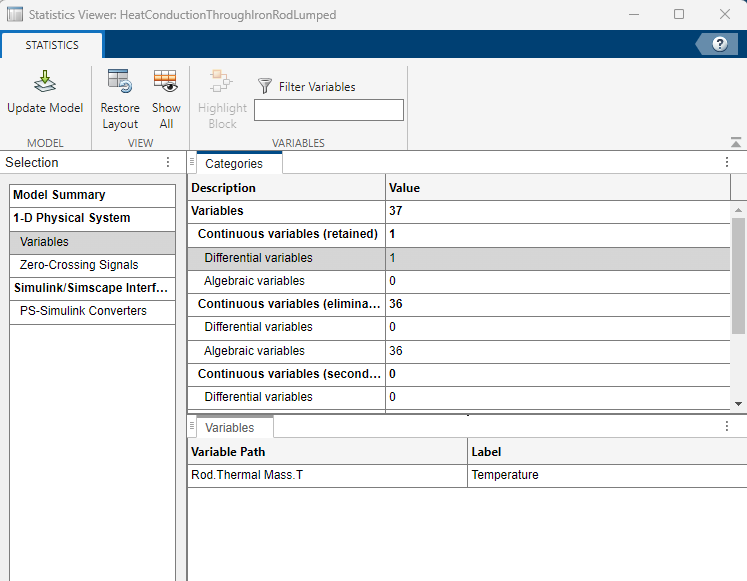

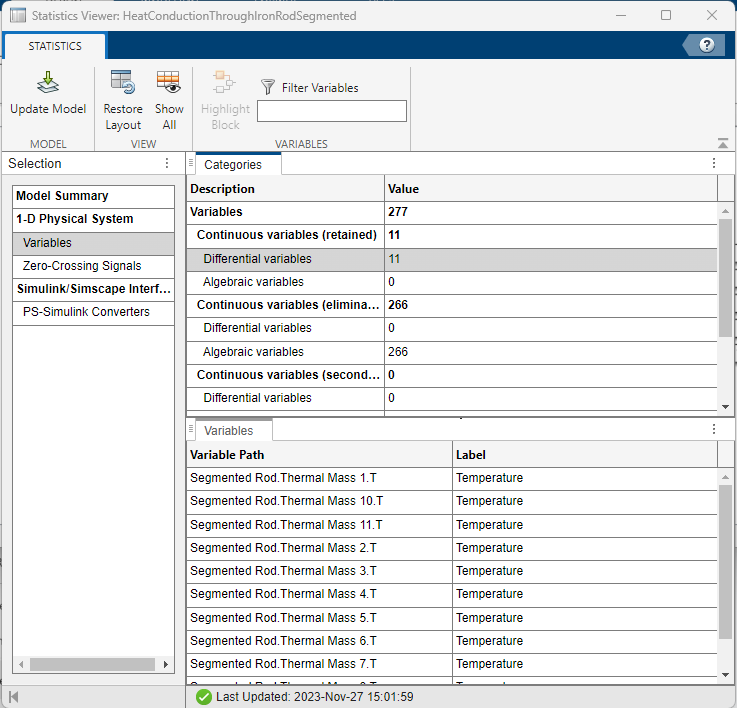

### Comparison to Steady State Analytical Solution

For a rod with a constant cross-sectional area subject to conduction and convection along its length, the differential equation governing steady-state temperature along the rod is:

$\frac{d^2T}{dx^2} - \frac{h \pi Dx}{kA}(T - T_{Air}) = 0$,

where $x$ is the longitudinal distance from the base.

This example considers a rod with the following boundary conditions:

- The base has a fixed temperature, $T\left(0\right)=T_B$.

- At the rod tip, heat transfer due to conduction equals heat transfer due to convection,

             
$$\textrm{hA}\left(T_{\textrm{Air}} -T\left(L\right)\right)=\textrm{kA}\frac{\textrm{dT}\left(L\right)}{\textrm{dx}}$$


The solution to the linear, homogeneous, second-order differential equation subject to the given boundary conditions is [1]:

$T(x)= \frac{ \text{cosh} \ m(L-x) \ + (h/mk) \ \text{sinh} \ m(L-x)}{\text{cosh} \ mL \ + (h/mk) \ \text{sinh} \ mL}(T_{B} - T_{Air}) + T_{Air}$,

where

$m^2 =\frac{h\pi D\;\;}{\textrm{kA}}$.

The rate of heat transfer through the rod base is:


$$Q_{Base}= \sqrt{h \pi DkA } (T_B-T_{Air})

\frac{ \text{sinh} \ mL \ + (h/mk) \ \text{cosh} \ mL}{\text{cosh} \ mL \ + (h/mk) \ \text{sinh} \ mL}$$


[1] Incropera, DeWitt, Bergman, Lavine, *Fundamentals of Heat and Mass Transfer*. 6th Ed, Section 3.6. John Wiley & Sons, 2006.

Calculate the analytical steady-state temperatures and heat flow for the rod parameters.

% Temperature at the mid-point
x = L/2;
m_eqn = sqrt(h*pi*D/(k*A));
T_mid_analytical_ss = ( cosh(m_eqn*(L-x)) + h/(m_eqn*k) * sinh(m_eqn*(L-x)) ) / ( cosh(m_eqn*L) + h/(m_eqn*k) * sinh(m_eqn*L) ) * (T_base - T_air) + T_air % [degC]
% heat flow out the base
Q_base_analytical_ss = sqrt(h*pi*D*k*A)*(T_base-T_air) * ( sinh(m_eqn*L) + h/(m_eqn*k) * cosh(m_eqn*L) ) / ( cosh(m_eqn*L) + h/(m_eqn*k) * sinh(m_eqn*L) ) % [W]

Plot the analytical steady-state solutions along with the simulated solutions. The plots below show the segmented model with 9 segments has nearly converged with the analytical solution while the single lumped mass model retains an error. Increasing the number of segments would further improve the convergence with the analytical prediction.

figure;
clf;
hold on;
plot([1000 2500], T_mid_analytical_ss*[1 1], 'LineWidth', 2)
plot(time_Lumped, T_Lumped, '--', 'Color', [0 0.6 0])
plot(time_Segmented, T_Segmented);
xlabel('Time (sec)')
title('Steady-State Temperature (degC)')
legend('Analytical solution', 'Lumped rod (midpoint)', 'Segment 1', 'Segment 3', 'Segment 5 (midpoint)', 'Segment 7', 'Segment 9', 'Location', 'best')
xlim([1000 2500]) % Zoom into the steady-state time region
% Plot the base heat transfer rate
figure;
clf;
hold on;
plot([1000 2500], Q_base_analytical_ss*[1 1], 'LineWidth', 2)
plot(time_Lumped, Q_Lumped, '--')
plot(time_Segmented, Q_Segmented);
xlabel('Time (sec)')
title('Steady-State Base Heat Flow')
legend('Analytical solution', 'Lumped rod', 'Segmented rod', 'Location', 'best')
xlim([1000 2500]) % Zoom into the steady-state time region

*Copyright 2008-2023 The MathWorks, Inc.*